## Task 1: Dilation and Erosion

(1) Dilation Operation

A = imread('assets/text-broken.tif');

% SE 1: cross (+)
B1 = [0 1 0;
      1 1 1;
      0 1 0]; % create structuring element
A1 = imdilate(A, B1);

% SE 2: all ones (3x3)
B2 = ones(3,3); 
A2 = imdilate(A, B2);

% SE 3: diagonal cross (X)
Bx = [1 0 1;
      0 1 0;
      1 0 1];
A3 = imdilate(A, Bx);

% Dilate twice using B1
A1_twice = imdilate(A1, B1);

% Show results
montage({A, A1, A2, A3, A1_twice})
title('Original | B1 (+) | B2 (ones) | Bx (X) | B1 twice')

（2）Generation of structuring element

SE = strel('disk',4);
SE.Neighborhood         % print the SE neighborhood contents

ans = 7×7 logical 数组
   0   0   1   1   1   0   0
   0   1   1   1   1   1   0
   1   1   1   1   1   1   1
   1   1   1   1   1   1   1
   1   1   1   1   1   1   1
   0   1   1   1   1   1   0
   0   0   1   1   1   0   0


(3) Erosion Operation

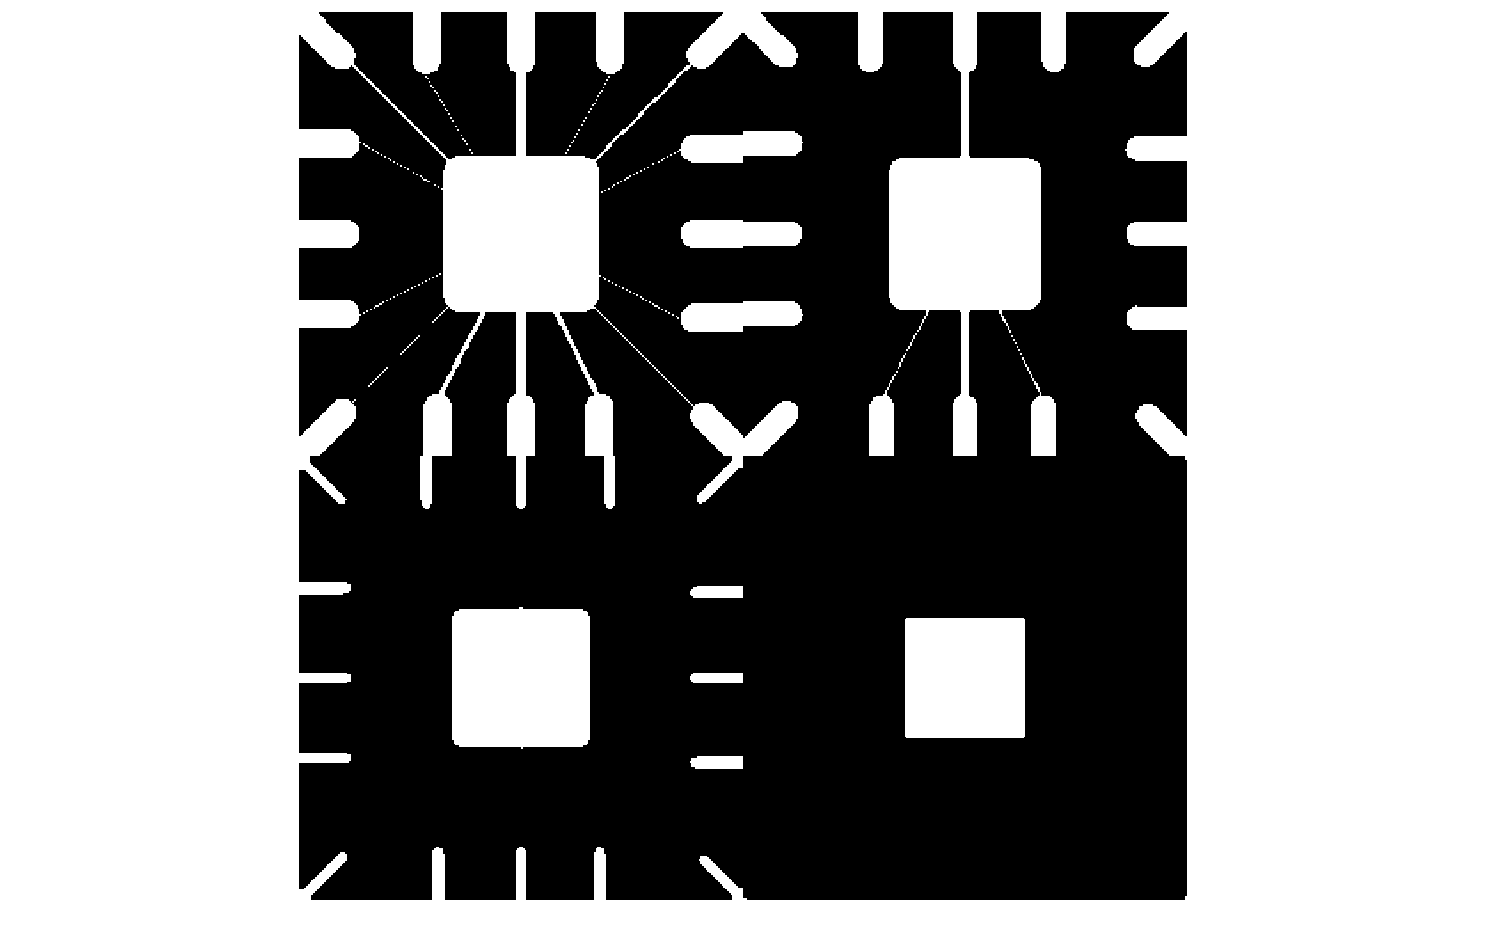

clear all
close all
A = imread('assets/wirebond-mask.tif');
SE2 = strel('disk',2);
SE10 = strel('disk',10);
SE20 = strel('disk',20);
E2 = imerode(A,SE2);
E10 = imerode(A,SE10);
E20 = imerode(A,SE20);
montage({A, E2, E10, E20}, "size", [2 2])

## Task 2 - Morphological Filtering with Open and Close

Opening = Erosion + Dilation

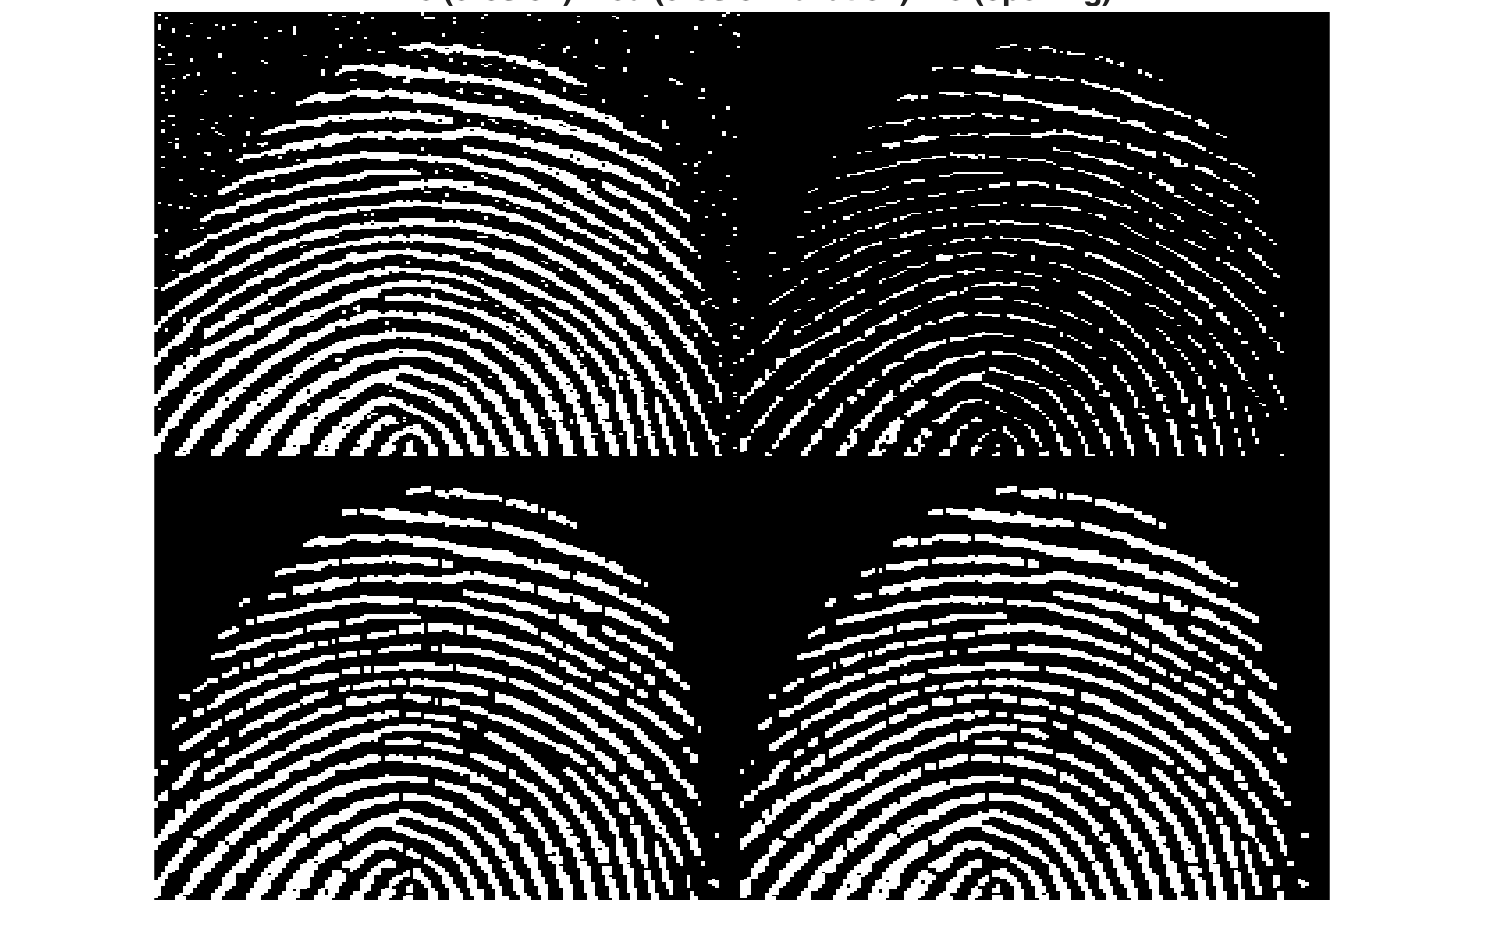

clear all
close all

% 1. Read the noisy finger image
f = imread('assets/fingerprint-noisy.tif');

% 2. Generate a 3×3 structuring element
SE = strel('square', 3);

% 3. Erode f → fe
fe = imerode(f, SE);

% 4. Dilate fe → fed
fed = imdilate(fe, SE);

% 5. Open f directly → fo
fo = imopen(f, SE);

% 6. Display results as a 4-image montage
montage({f, fe, fed, fo}, 'Size', [2 2])
title('f | fe (erosion) | fed (erosion+dilation) | fo (opening)')

Explore other size/shape of SE

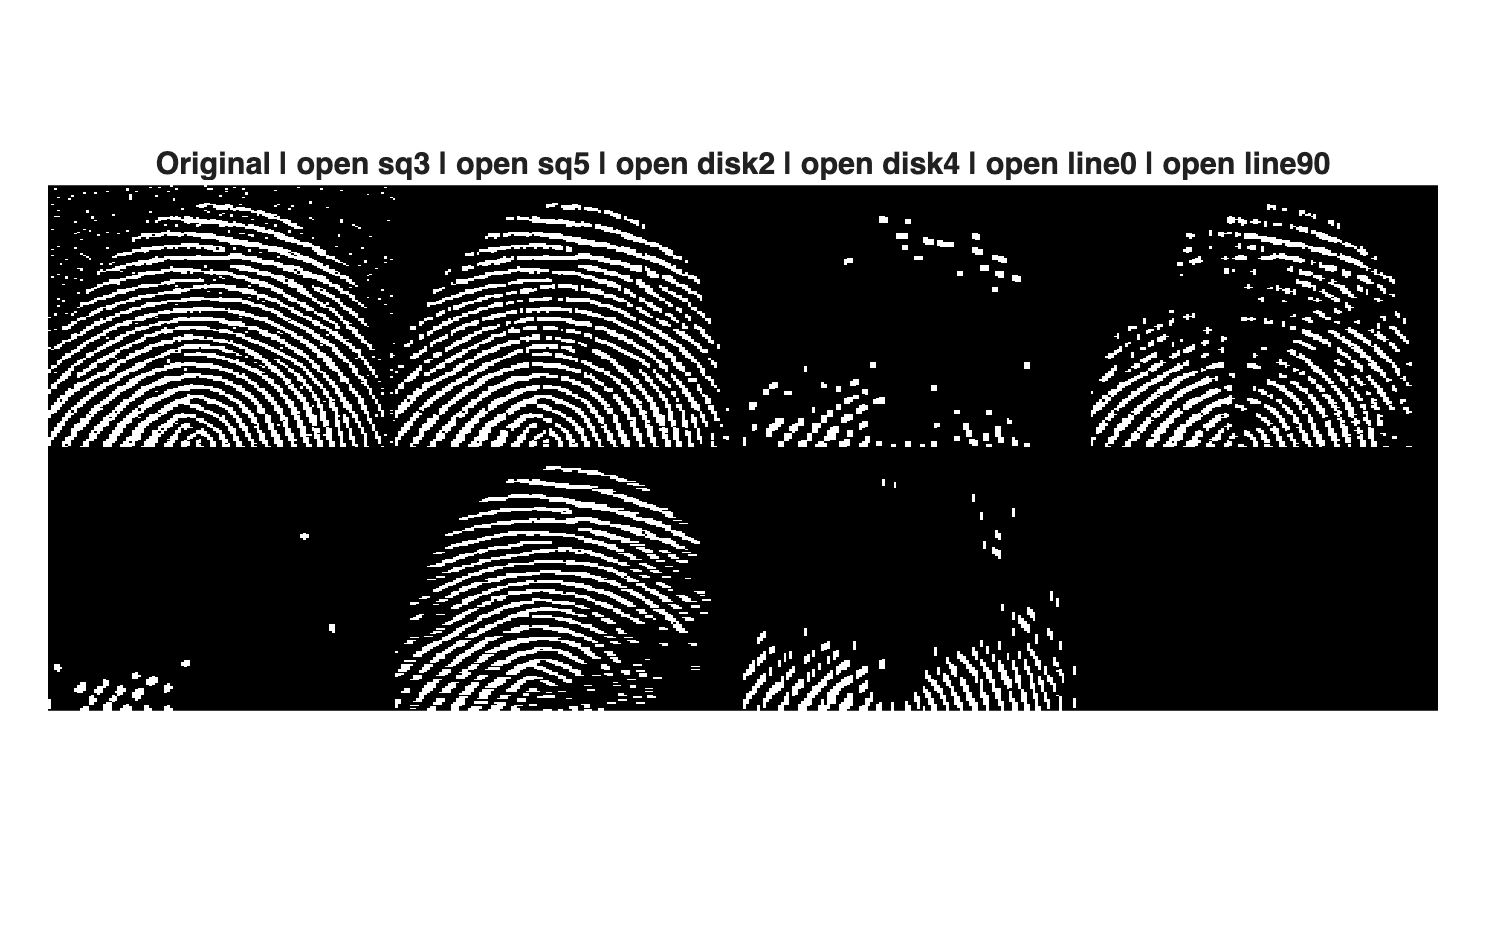


f = imread('assets/fingerprint-noisy.tif');

% Different structuring elements
SE_sq3  = strel('square', 3);
SE_sq5  = strel('square', 5);
SE_disk2 = strel('disk', 2);
SE_disk4 = strel('disk', 4);
SE_line7 = strel('line', 7, 0);     % horizontal line
SE_line7v = strel('line', 7, 90);   % vertical line

fo_sq3   = imopen(f, SE_sq3);
fo_sq5   = imopen(f, SE_sq5);
fo_disk2 = imopen(f, SE_disk2);
fo_disk4 = imopen(f, SE_disk4);
fo_lineH = imopen(f, SE_line7);
fo_lineV = imopen(f, SE_line7v);

montage({f, fo_sq3, fo_sq5, fo_disk2, fo_disk4, fo_lineH, fo_lineV}, 'Size', [2 4])
title('Original | open sq3 | open sq5 | open disk2 | open disk4 | open line0 | open line90')

3) Improve fo with a close operation

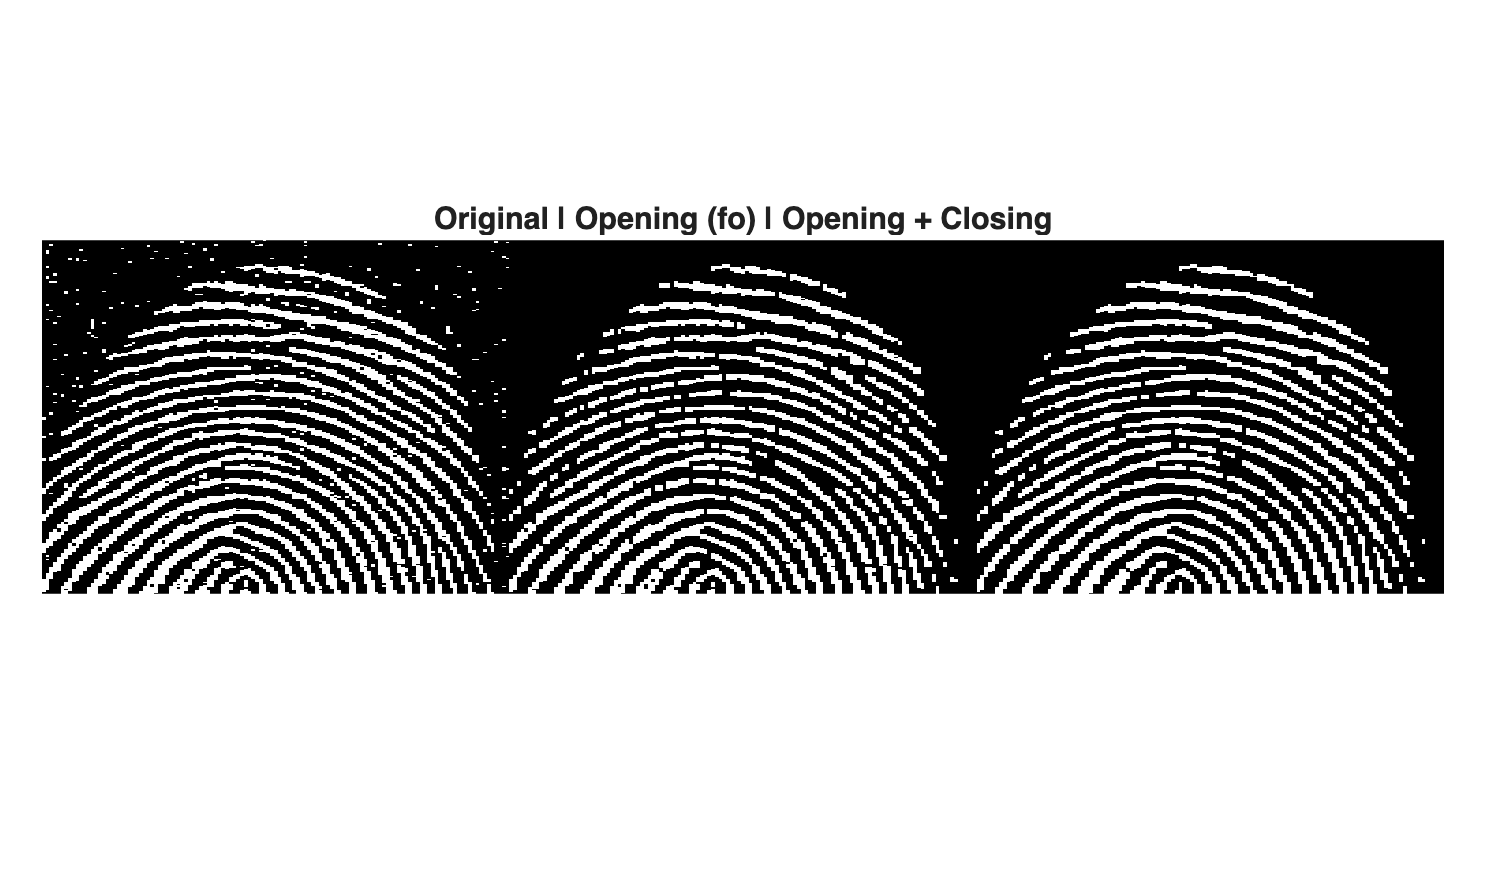

SE = strel('square', 3);  

fo = imopen(f, SE);        
fo_close = imclose(fo, SE); % improve fo using closing

montage({f, fo, fo_close}, 'Size', [1 3])
title('Original | Opening (fo) | Opening + Closing')

4) Compare Open+Close vs Gaussian spatial filter

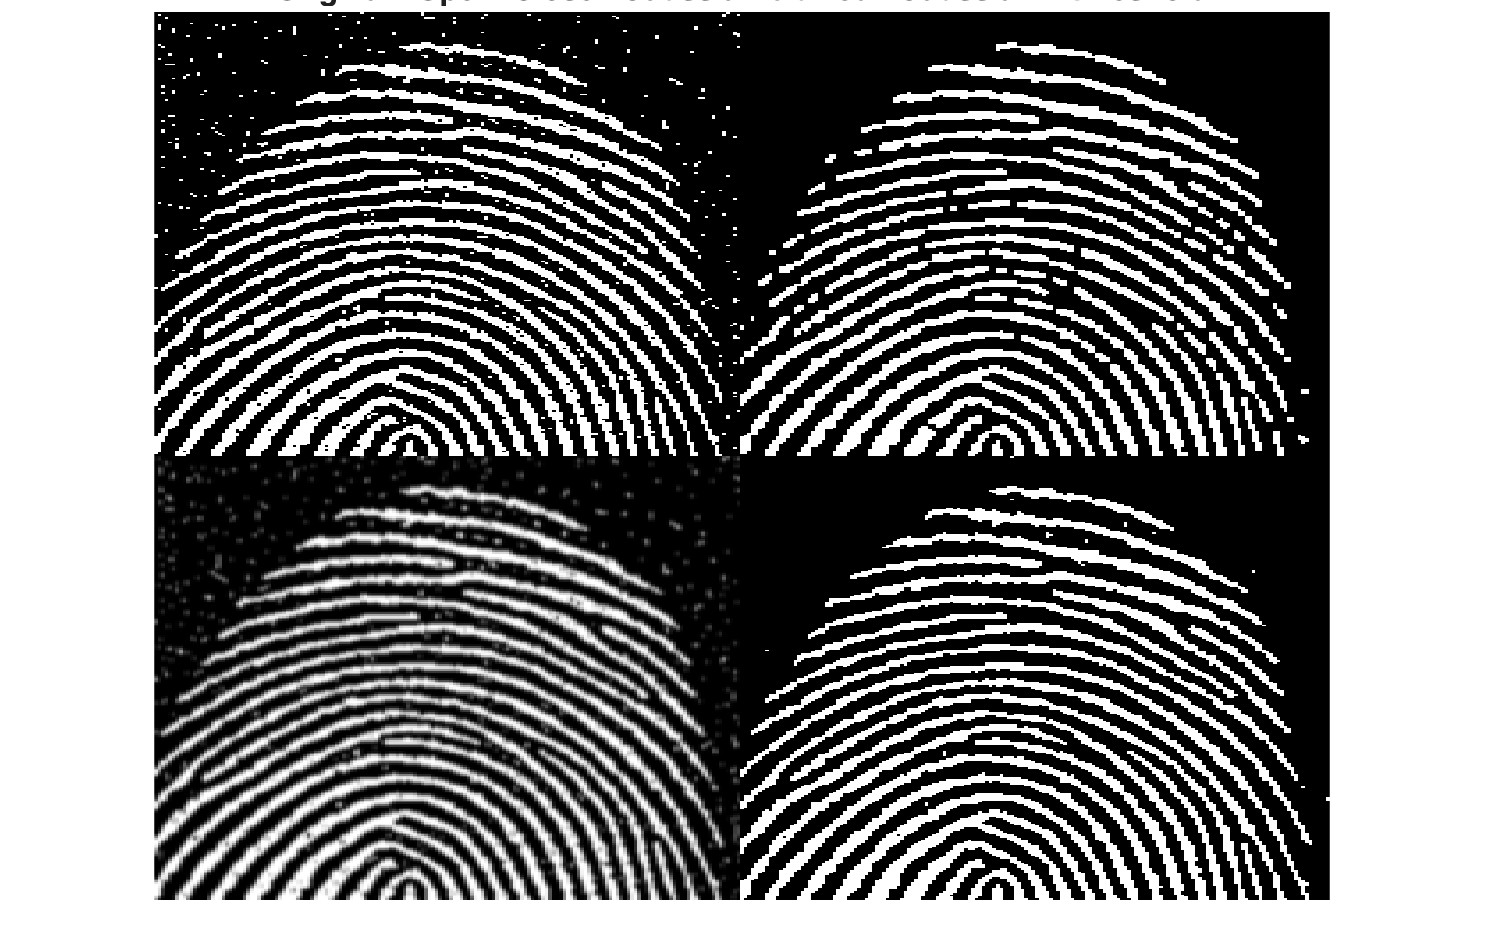

SE = strel('square', 3);

% Morphological filtering: Open + Close
f_oc = imclose(imopen(f, SE), SE);

% Gaussian spatial filter (needs grayscale -> threshold)
fg = im2double(f);
fg_blur = imgaussfilt(fg, 1.0);         % sigma=1.0
fg_bin = fg_blur > 0.5;                  % threshold 

montage({f, f_oc, fg_blur, fg_bin}, 'Size', [2 2])
title('Original | Open+Close | Gaussian blurred | Gaussian + threshold')

## Task 3 - Boundary detection

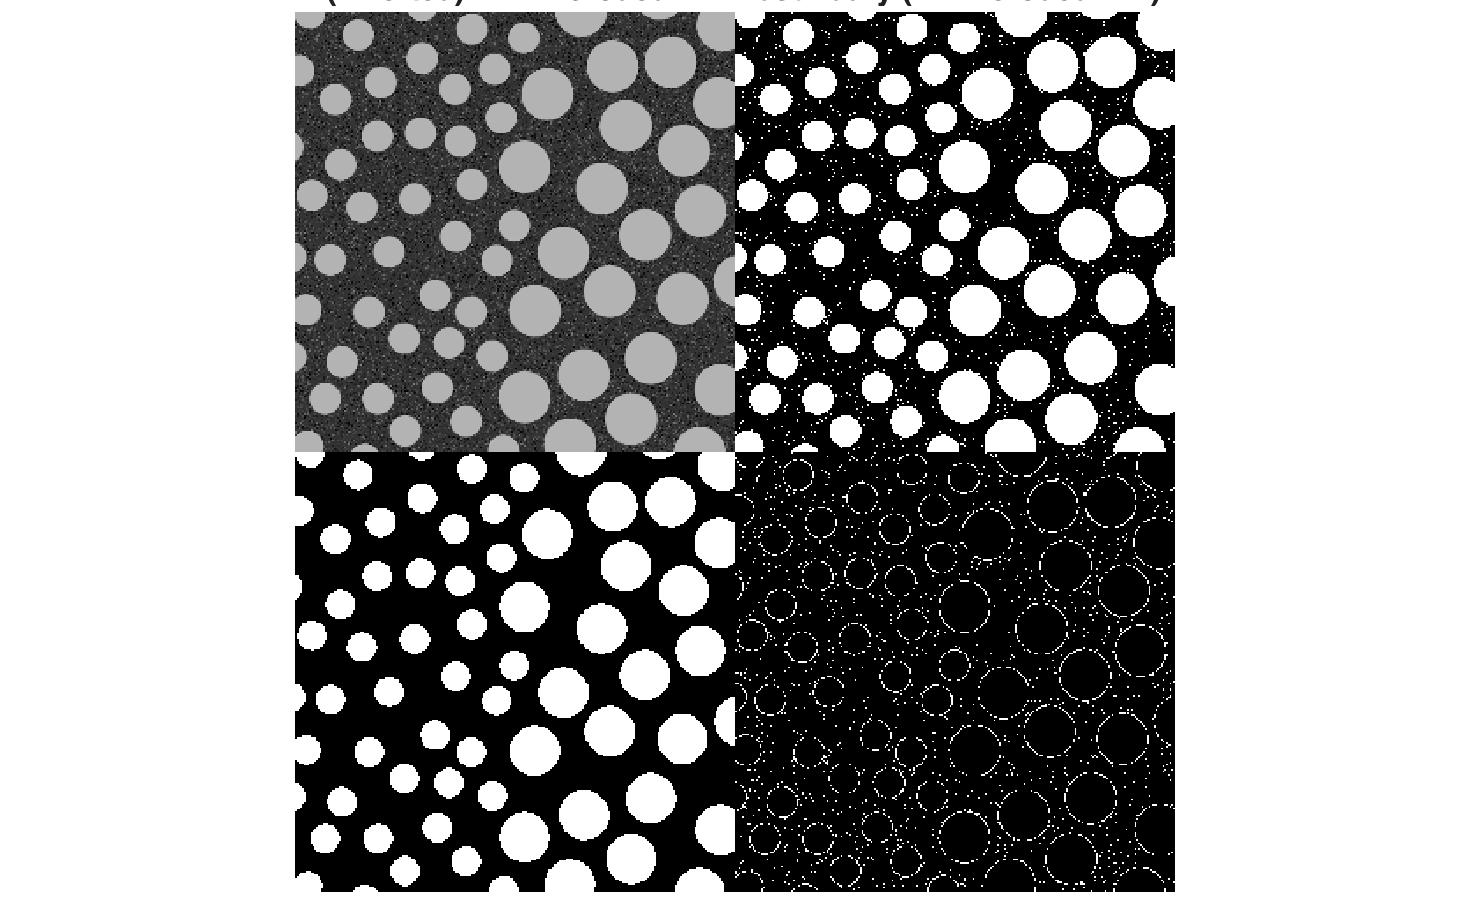

clear all
close all
I = imread('assets/blobs.tif');
I = imcomplement(I);
level = graythresh(I);
BW = imbinarize(I, level);

% Morphological boundary operator:

SE = ones(3,3);                   % 3x3 SE of 1s (as required)
BW_eroded = imerode(BW, SE);      
boundary = BW & ~BW_eroded;       


montage({I, BW, BW_eroded, boundary}, 'Size', [2 2])
title('I (inverted) | BW | eroded BW | boundary (BW - eroded BW)')

task 4

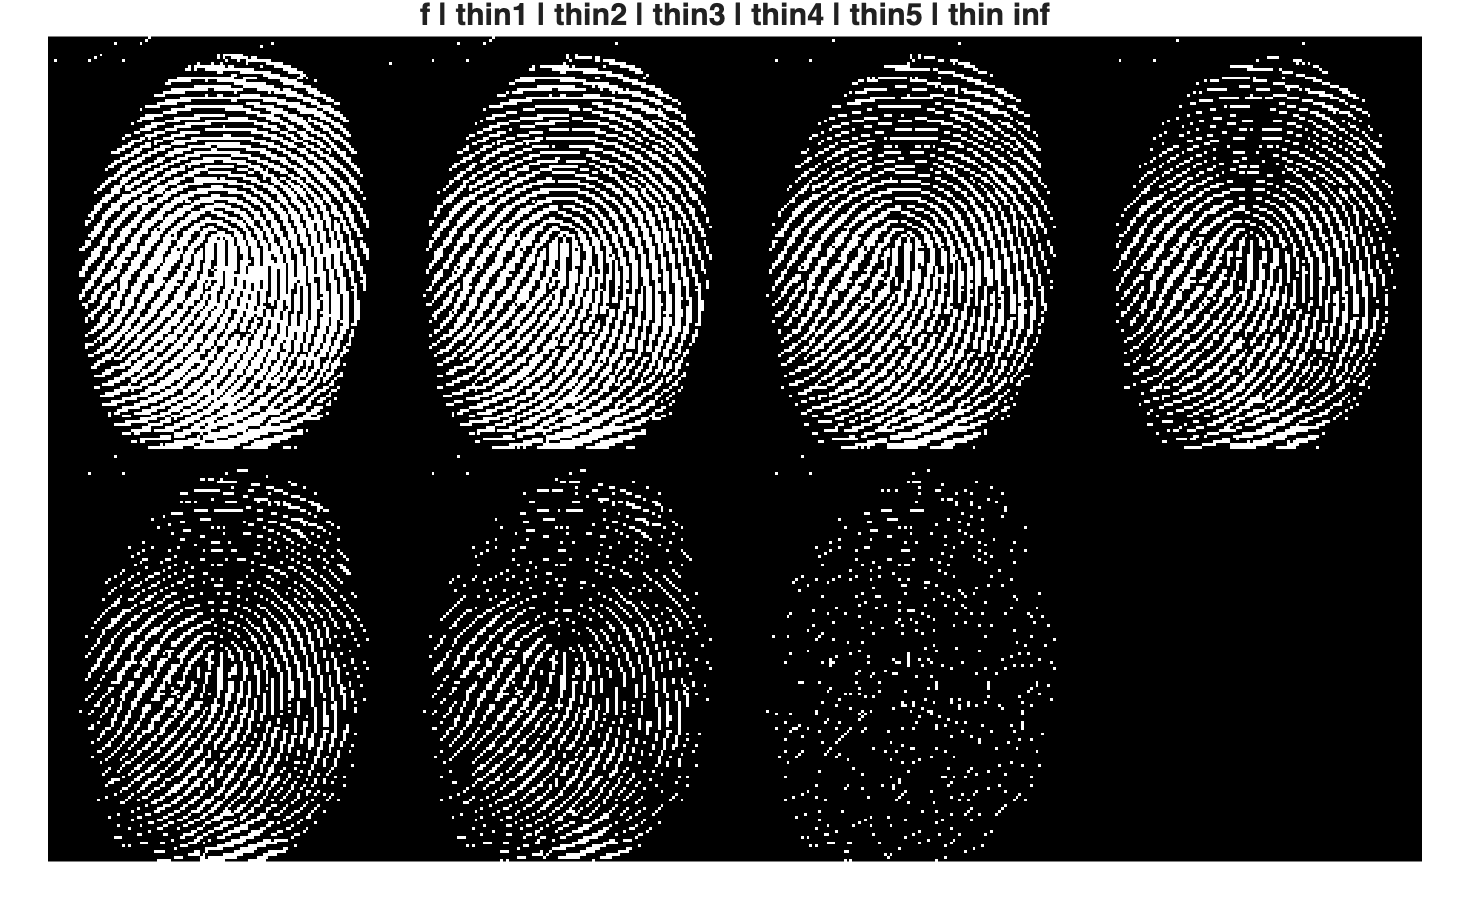

clear all
close all

% 1. Read fingerprint image
I = imread('assets/fingerprint.tif');

% 2. Convert to binary (same method as previous task)
I = imcomplement(I);
level = graythresh(I);
f = imbinarize(I, level);

% 3. Thinning for n = 1..5 and inf
g1 = bwmorph(f, 'thin', 1);
g2 = bwmorph(f, 'thin', 2);
g3 = bwmorph(f, 'thin', 3);
g4 = bwmorph(f, 'thin', 4);
g5 = bwmorph(f, 'thin', 5);
ginf = bwmorph(f, 'thin', inf);

% 4. Display comparison
montage({f, g1, g2, g3, g4, g5, ginf}, 'Size', [2 4])
title('f | thin1 | thin2 | thin3 | thin4 | thin5 | thin inf')

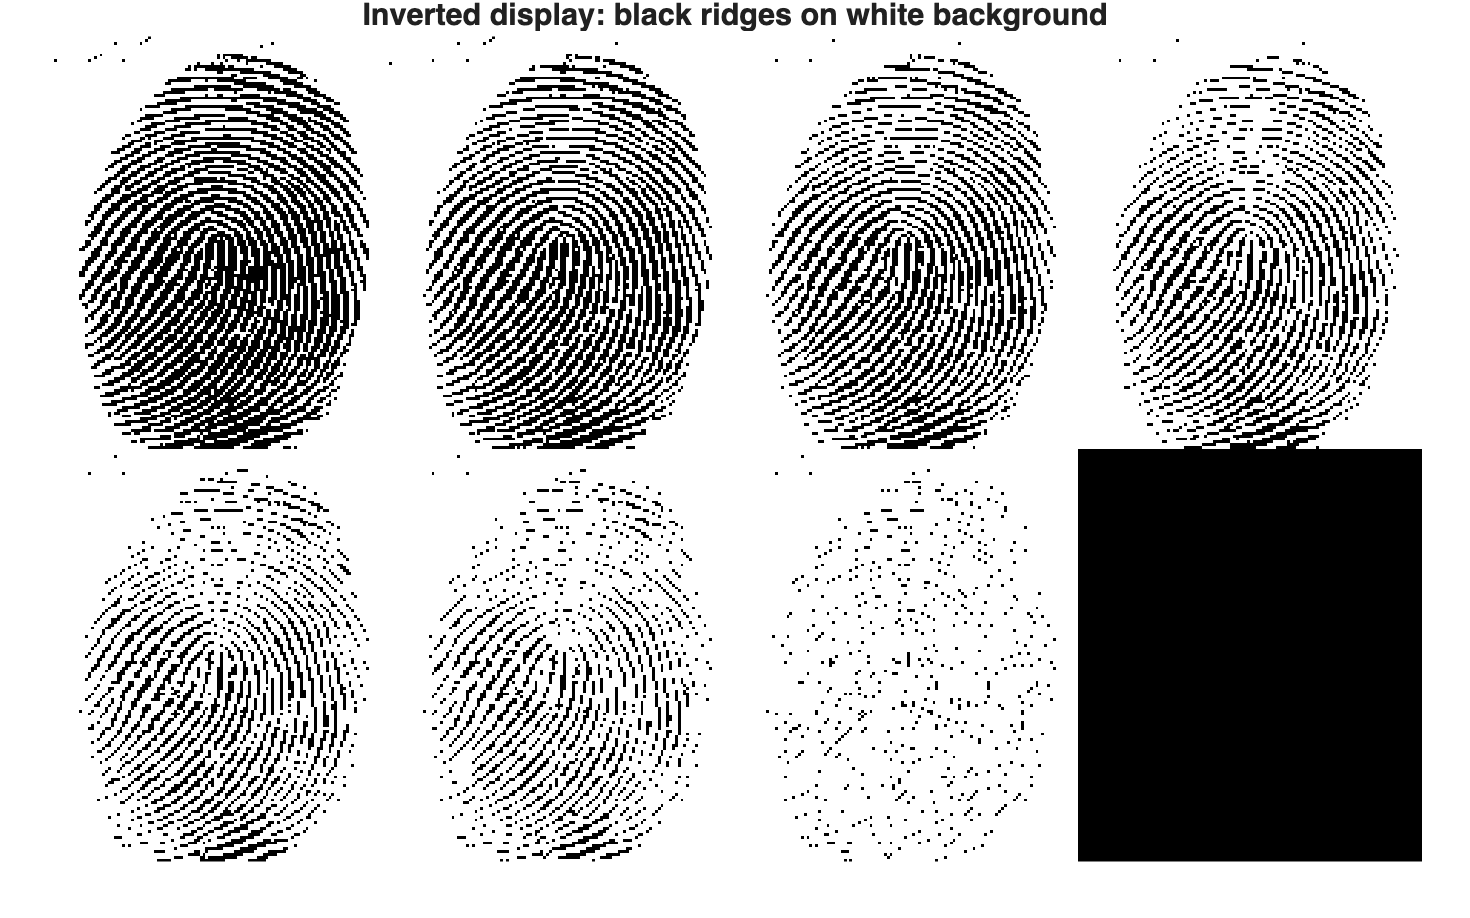

montage({~f, ~g1, ~g2, ~g3, ~g4, ~g5, ~ginf}, 'Size', [2 4])
title('Inverted display: black ridges on white background')

task 5

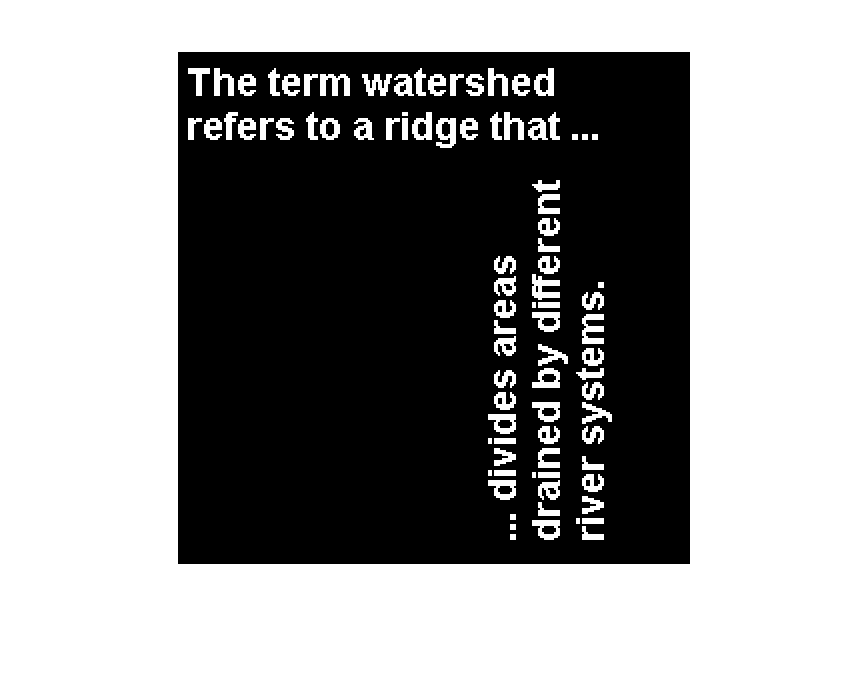

clear
t = imread('assets/text.png');
imshow(t)

CC = bwconncomp(t)

CC = 包含以下字段的 struct:
    Connectivity: 8
       ImageSize: [256 256]
      NumObjects: 88
    PixelIdxList: {1×88 cell}


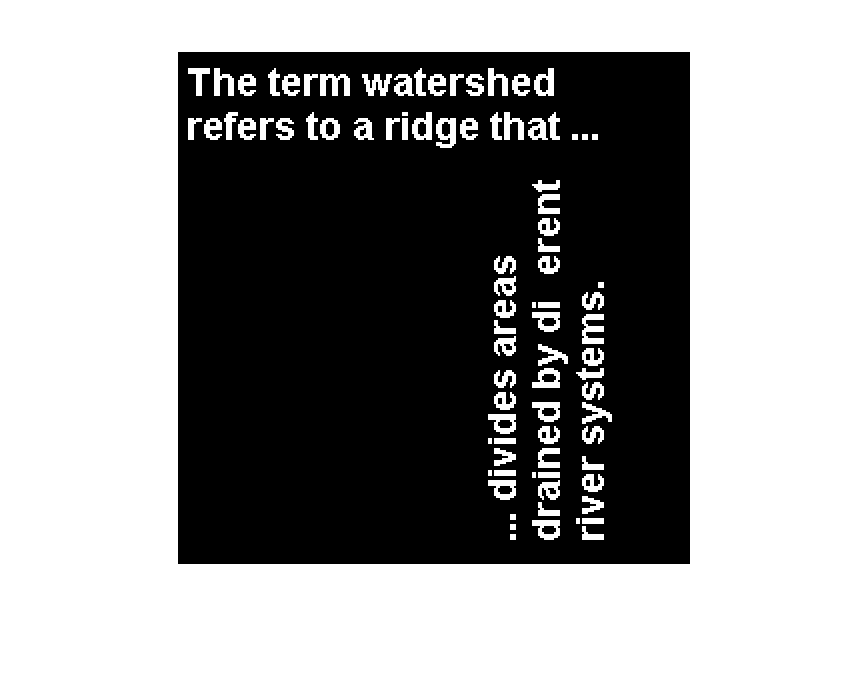

numPixels = cellfun(@numel, CC.PixelIdxList);
[biggest, idx] = max(numPixels);
t(CC.PixelIdxList{idx}) = 0;
figure
imshow(t)

## Task 6 - Morphological Reconstruction

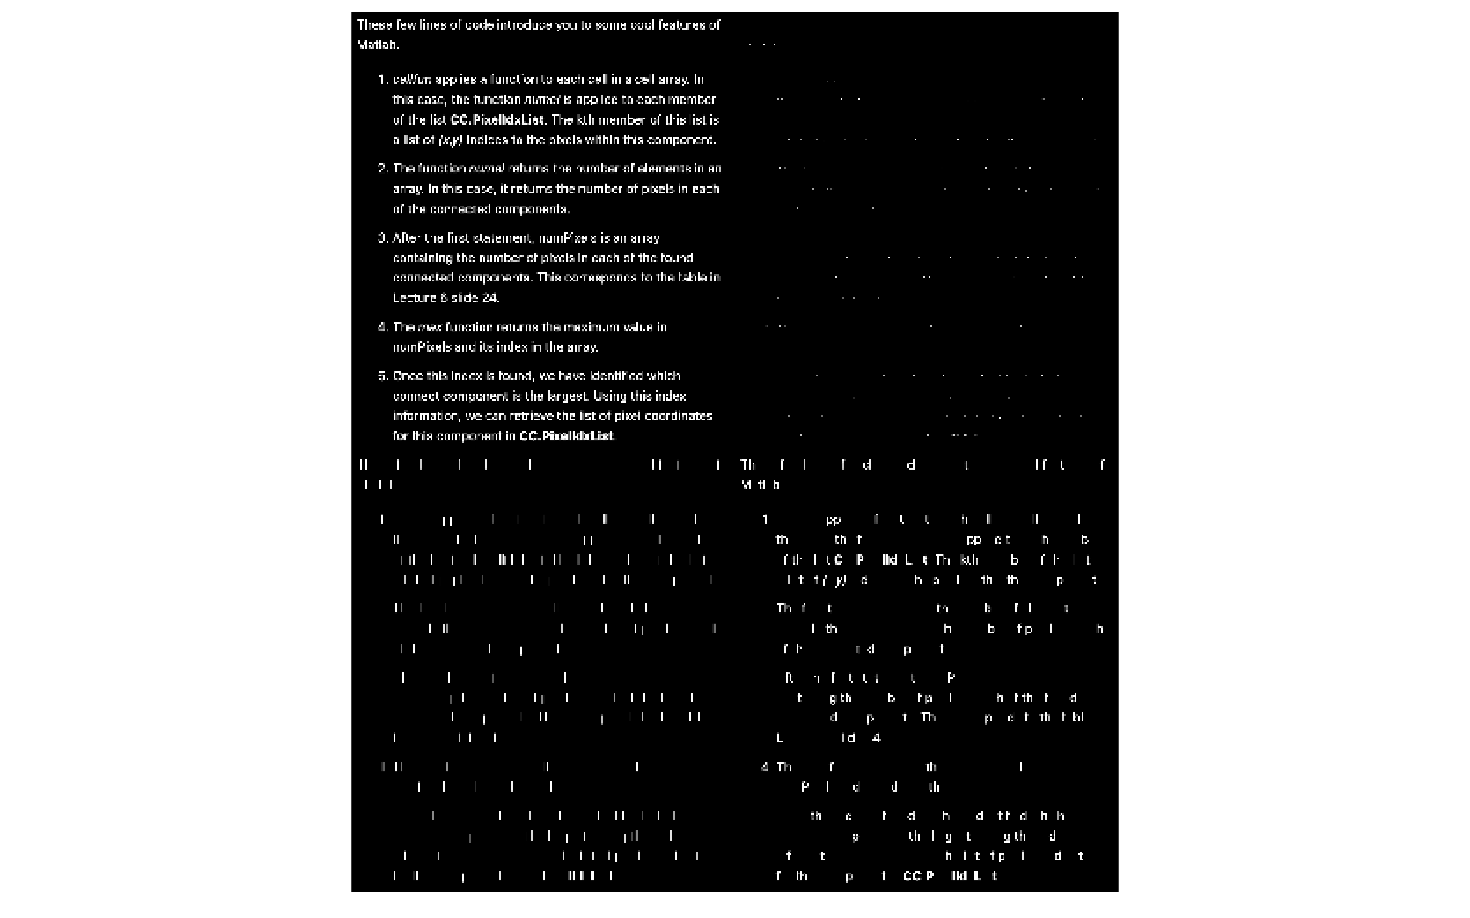

clear all
close all
f = imread('assets/text_bw.tif');
se = ones(17,1);
g = imerode(f, se);
fo = imopen(f, se);     % perform open to compare
fr = imreconstruct(g, f);
montage({f, g, fo, fr}, "size", [2 2])

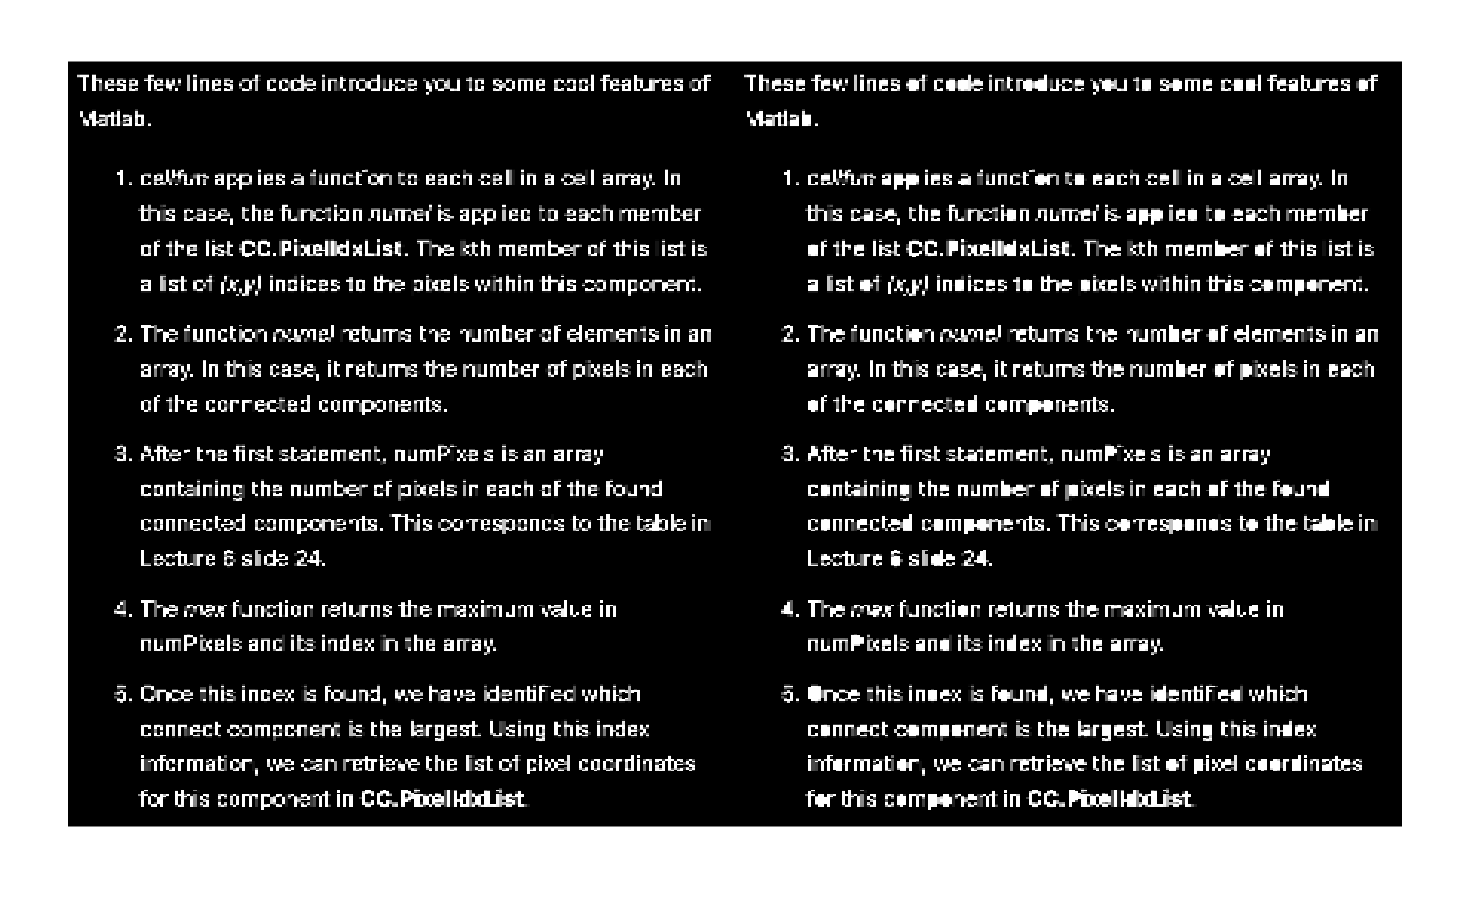

ff = imfill(f);
figure
montage({f, ff})

task 7

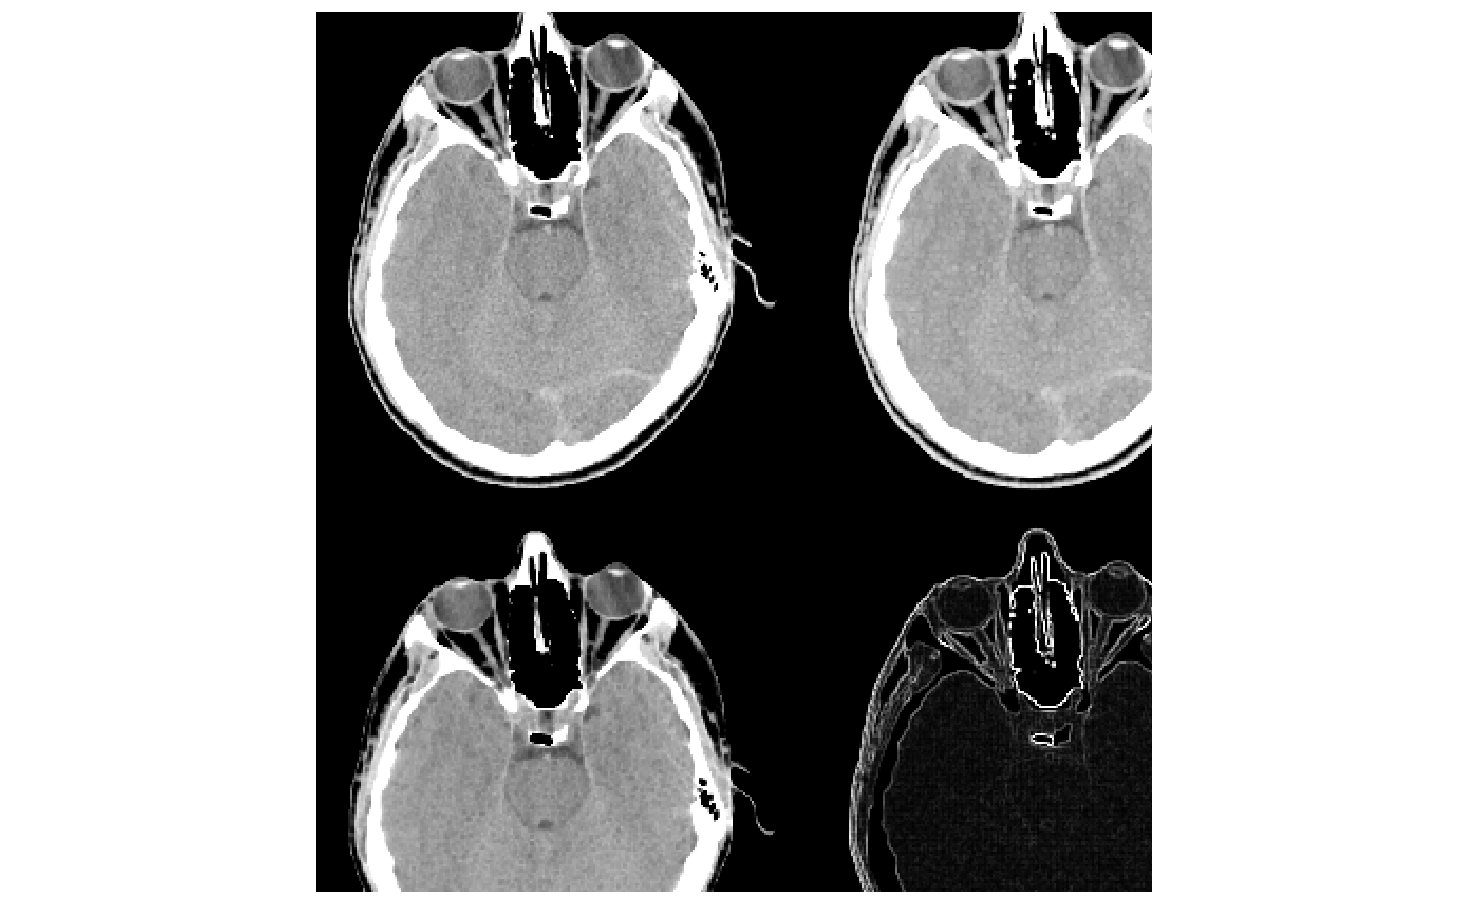

clear all; close all;
f = imread('assets/headCT.tif');
se = strel('square',3);
gd = imdilate(f, se);
ge = imerode(f, se);
gg = gd - ge;
montage({f, gd, ge, gg}, 'size', [2 2])

Challenges 1


clear; close all; clc;

% 1) Read image
I = imread('assets/fillings.tif');

% If image is RGB, convert to grayscale
if ndims(I) == 3
    I = rgb2gray(I);
end

% 2) Denoise + contrast enhance (simple + common for X-ray)
I_f = medfilt2(I, [3 3]);         
I_e = imadjust(I_f);             

% 3) Segment bright fillings (global threshold)
level = graythresh(I_e);
BW = imbinarize(I_e, level);

% If your fillings become black (0) and background is white (1), invert:
% BW = ~BW;

% 4) Morphological clean-up (remove small noise, fill small gaps)
BW = bwareaopen(BW, 50);               
BW = imclose(BW, strel('disk', 2));     
BW = imfill(BW, 'holes');              

% 5) Connected components + area (pixel count)
CC = bwconncomp(BW);
stats = regionprops(CC, 'Area', 'Centroid');

areas = [stats.Area]';           
num_fillings = numel(areas);

% Sort by size (largest first)
[areas_sorted, order] = sort(areas, 'descend');

% 6) Print results
fprintf('Number of fillings detected: %d\n', num_fillings);

Number of fillings detected: 6


fprintf('Fillings area (pixels), sorted (largest->smallest):\n');

Fillings area (pixels), sorted (largest->smallest):


disp(areas_sorted);

      231835
      190171
         823
         437
         306
          64



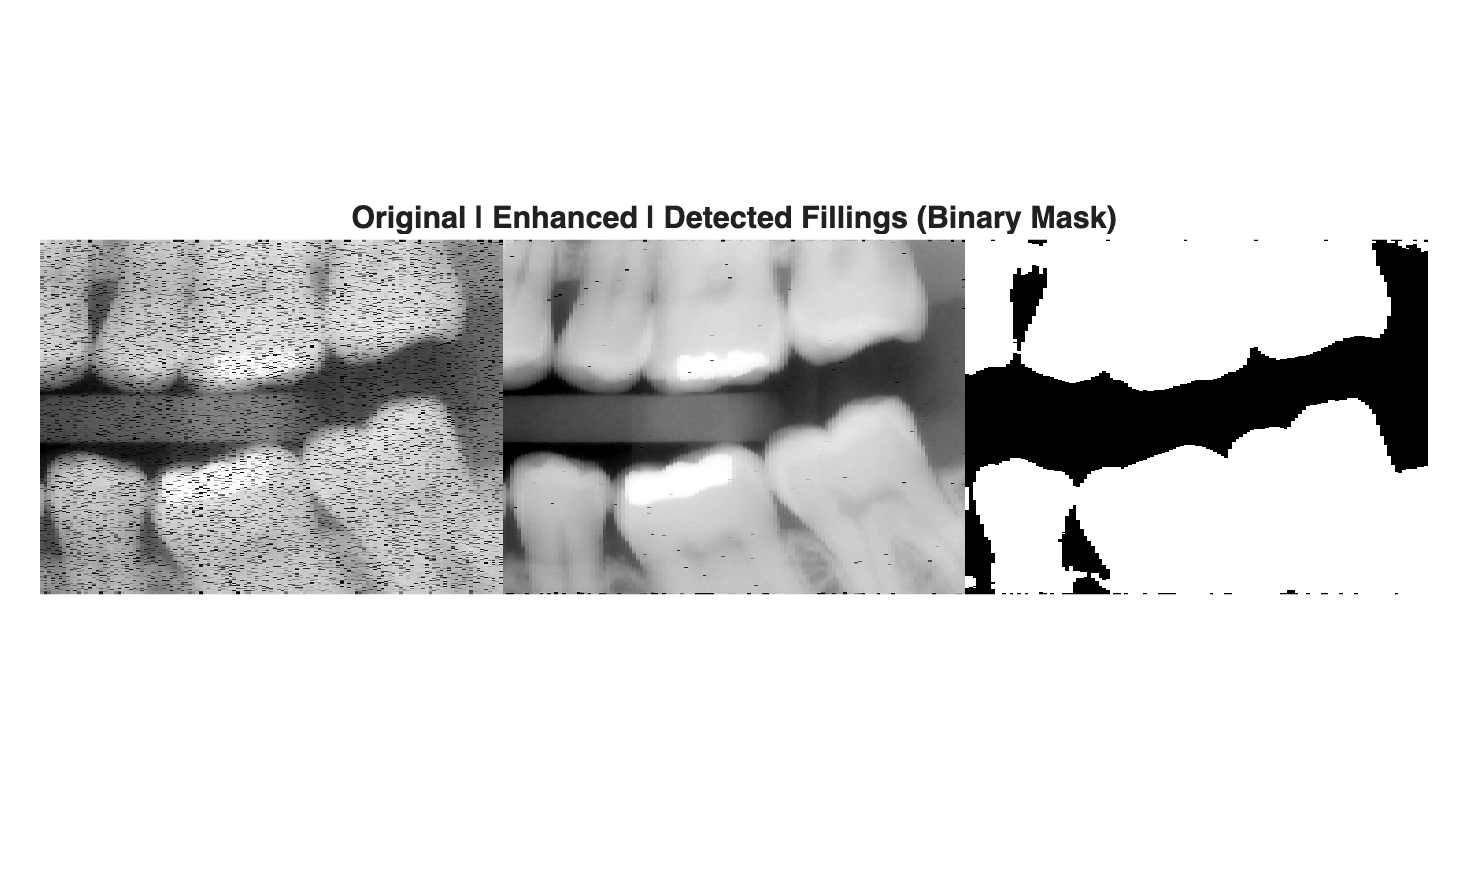


% 7) Visual check: show original + mask + overlay labels
figure;
montage({I, I_e, BW}, 'Size', [1 3]);
title('Original | Enhanced | Detected Fillings (Binary Mask)');

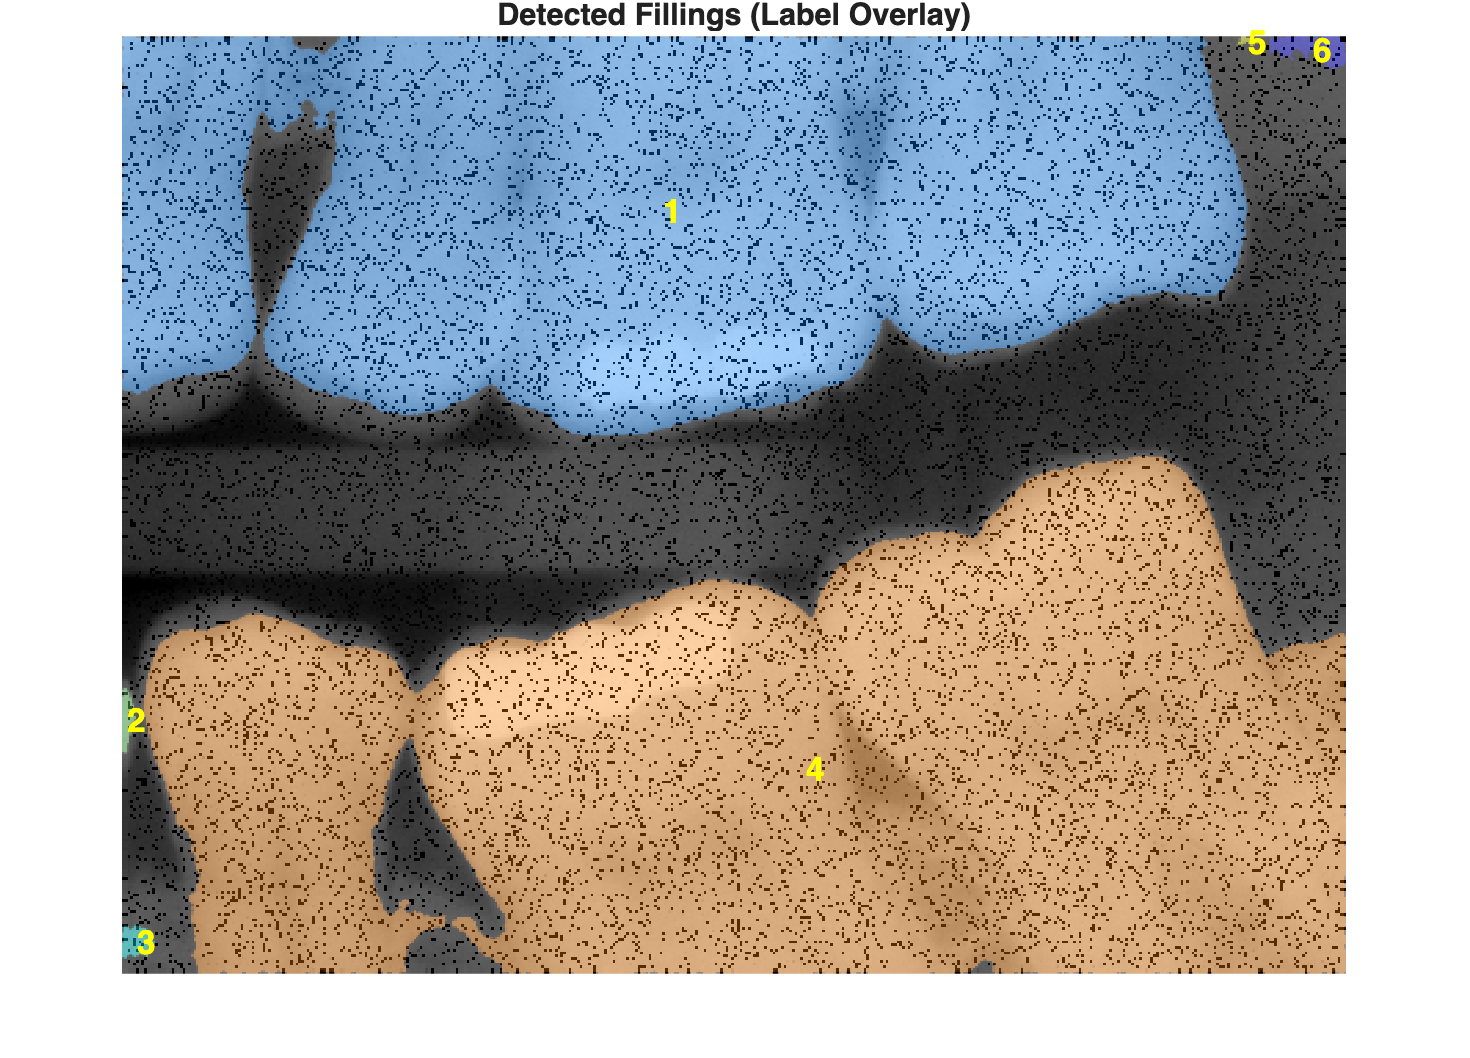


% Label overlay
L = labelmatrix(CC);
RGB = label2rgb(L, 'jet', 'k', 'shuffle');

figure;
imshow(I); hold on;
h = imshow(RGB);
set(h, 'AlphaData', 0.35);  % transparent overlay
title('Detected Fillings (Label Overlay)');

% Optional: label each filling with an index number at centroid
for k = 1:num_fillings
    c = stats(k).Centroid;
    text(c(1), c(2), sprintf('%d', k), 'Color', 'y', 'FontSize', 12, 'FontWeight', 'bold');
end
hold off;

challenge 2

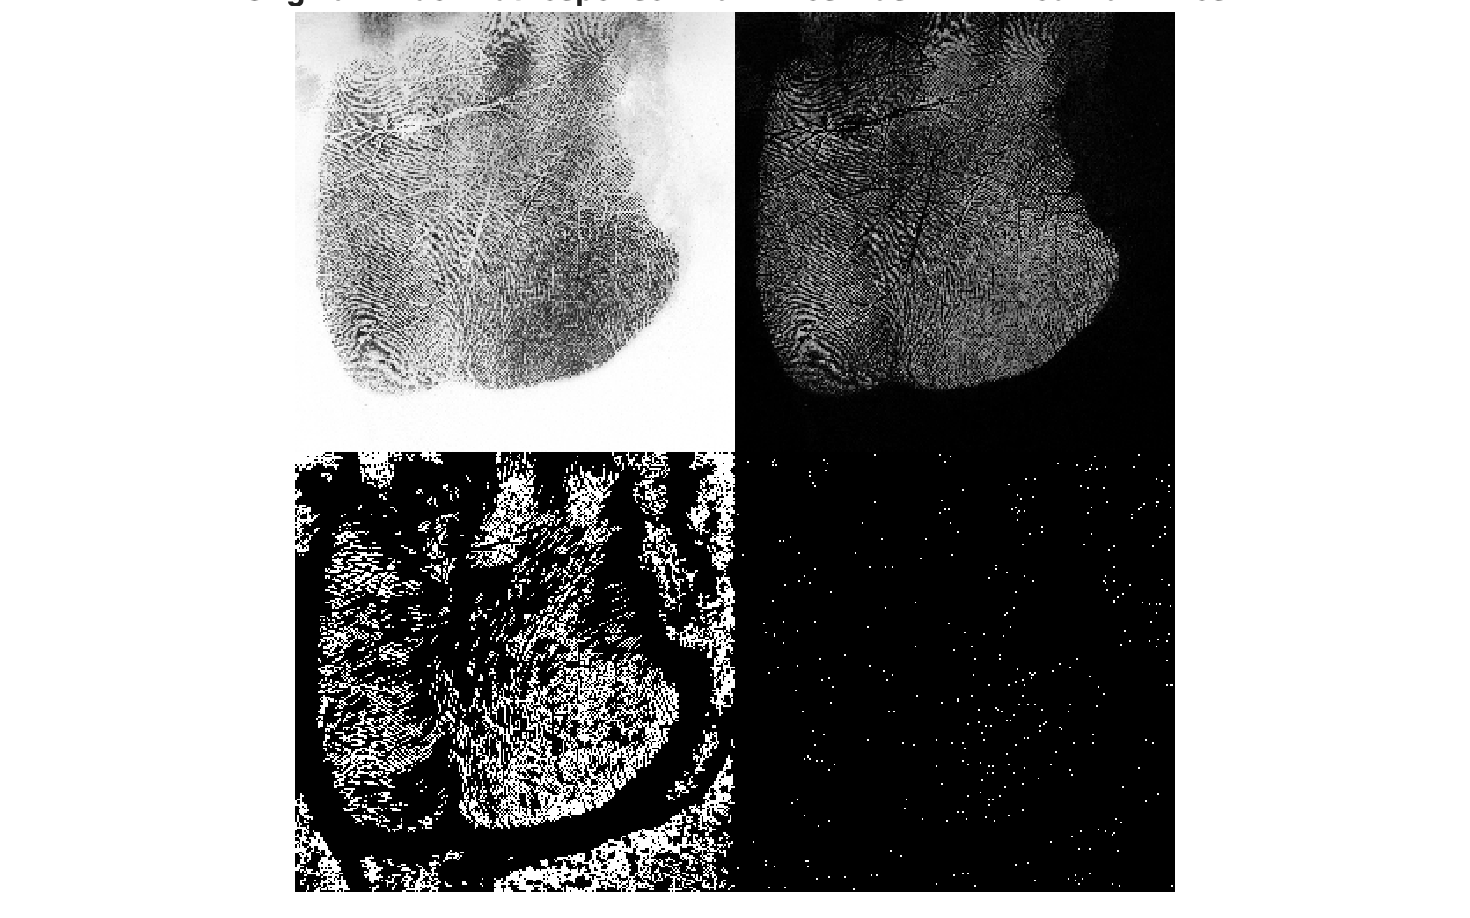


clear all; close all;

% 1) Read grayscale palm image
I = imread('assets/palm.tif');
if size(I,3) > 1
    I = rgb2gray(I);
end
I = im2uint8(I);

% 2) Denoise slightly (reduce small texture/noise)
I_s = medfilt2(I, [3 3]);

% 3) Enhance dark main lines using black-hat (closing - image)
r = 10;                          
se = strel('disk', r);
Bh = imbothat(I_s, se);

% 4) Binarise the line response
BW = imbinarize(Bh, 'adaptive', ...
    'ForegroundPolarity', 'bright', ...
    'Sensitivity', 0.5);        

% 5) Clean up: remove tiny fragments and connect gaps
BW = bwareaopen(BW, 200);        
BW = imclose(BW, strel('disk', 2));

% (optional) Thin to 1-pixel centreline
BW_thin = bwmorph(BW, 'thin', inf);

% 6) Show results
figure;
montage({I, Bh, BW, BW_thin}, 'Size', [2 2]);
title('Original | Black-hat response | Main lines mask | Thinned main lines');